clear
clc

system("make main -f .\Makefile");

make: Nothing to be done for 'main'.



ind = 1;
N_range = 100 : 100 : 2000;
for N = N_range
    N
    system(".\FiniteDifferences.exe " + string(N) + " " + string(N));
    M = N;
    
    v1.x = round((131.25)/400 * N);
    v1.y = round((125)/250 * N);
    v2.x = round((400-131.25)/400 * N);
    v2.y = round((125)/250 * N);
    
    v3.x = round((151.39)/400 * N);
    v3.y = round((250 - 76.39)/250 * N);
    v4.x = round((400 - 151.39)/400 * N);
    v4.y = round((76.39)/250 * N);
    
    x = load(".\x.txt");
 
    %DV(ind) = abs(phi(v1.y,v1.x) - phi(v2.y,v2.x));
    DV1(ind) = abs(x(v1.x + N * (v1.y - 1)) - x(v2.x + N * (v2.y - 1))); %#ok [V]
    DV2(ind) = abs(x(v3.x + N * (v3.y - 1)) - x(v4.x + N * (v4.y - 1))); %#ok [V]
    ind = ind + 1;
end

N = 100

N = 200

N = 300

N = 400

N = 500

N = 600

N = 700

N = 800

N = 900

N = 1000

N = 1100

N = 1200

N = 1300

N = 1400

N = 1500

N = 1600

N = 1700

N = 1800

N = 1900

N = 2000

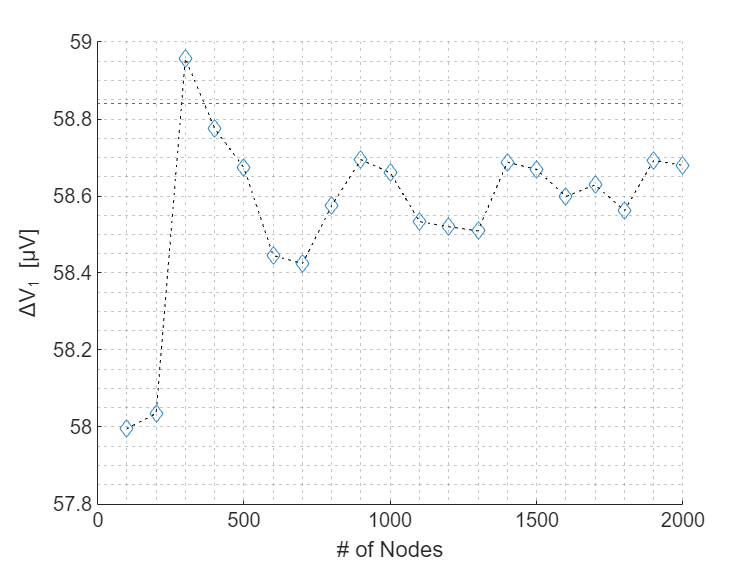

DV_th_1 = 58.84;
DV_th_2 = 39.31;

figure();
scatter(N_range,DV1 * 1e6,'d');
hold on
plot(N_range,DV1 * 1e6,'k:');
hold off
grid minor
xlabel('# of Nodes')
ylabel('ΔV_1 [μV]')
yline(DV_th_1,':');


% figure();
% scatter(N_range,DV2 * 1e6,'d');
% hold on
% plot(N_range,DV2 * 1e6,'k:');
% hold off
% grid minor
% xlabel('# of Nodes')
% ylabel('ΔV_2 [μV]')
% yline(DV_th_2,':');

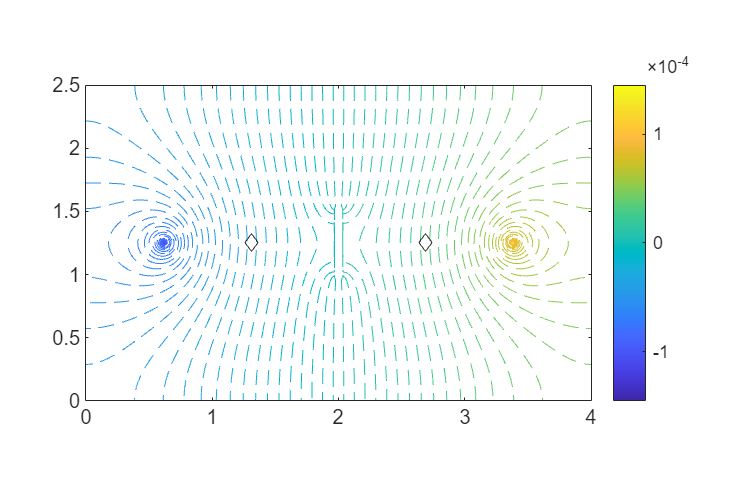

phi = zeros(M,N);
for i = 1:N
    for j = 1:M
        phi(j,i) = x(i + N * (j-1));
    end
end

figure("Position",[0,0,600,350]);
X_range = linspace(0,4.0,size(phi,2));
Y_range = linspace(0,2.5,size(phi,1));
Dx = X_range(2) - X_range(1);
Dy = Y_range(2) - Y_range(1);
contour(X_range,Y_range,phi,100,'LineStyle',"--")
hold on
scatter(Dx*v1.x,Dy*v1.y,'kd')
scatter(Dx*v2.x,Dy*v2.y,'kd')
hold off
grid off
axis equal
colorbar()